% load MNIST dataset
[XTest,YTest] = digitTest4DArrayData;

% load neural network
modelfile = "mnist_sigmoid_6_200.onnx";
nn = neuralNetwork.readONNXNetwork(modelfile, false, 'BCSS');

% sample image
idx = 251;
x = XTest(:,:,:,idx);           % image
label = double(YTest(idx))-1;   % label (dim=1 is label=0)

% construct uncertain input
r = 0.001; % perturbation radius
c = reshape(x,[],1);
G = eye(length(c)) * r;
X = zonotope(c,G);

% check correct classification of point
y_pred = nn.evaluate(c);
[~,label_pred] = max(y_pred);
label_pred = label_pred - 1;
fprintf("Correct classification: %d", label == label_pred);

Correct classification: 1


% parameters
evParams = struct;
evParams.poly_method = 'regression';

% propagate set through network
Y = nn.evaluate(X,evParams);

% compute lower bound of correct label
lb_label = interval(project(Y,label+1)).inf;

% verified if larger than all other dimensions
res = true;
for i=1:10
    if i ~= label+1
        res = res && interval(project(Y,i)).sup <= lb_label;
    end
end
fprintf("Verified: %d", res);

Verified: 1

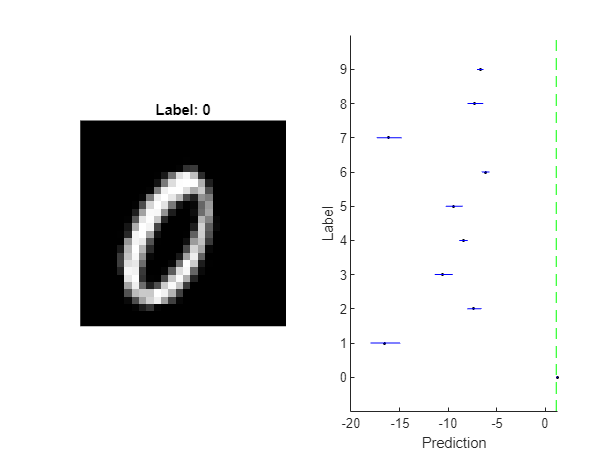


% plot --------------------------------------------------------------------

figure;
subplot(1,2,1);
imshow(x);
title(sprintf('Label: %d',label))

subplot(1,2,2); hold on;
for i=1:10
    scatter(y_pred(i),i-1,'.k');        % plot point prediction
    plot(Y,i,'b','YPos',i-1);           % plot set prediction
end
plot([lb_label,lb_label],[-1,10],'--g') % plot verification threshold

xlabel('Prediction')
ylabel('Label')
yticks(0:9)
ylim([-1,10])


exportToHTML(); % for website